active_expt_index = 1;
current_binning_index = 1;

active_binning_resolution = across_experiment_results{active_expt_index}.processing_config.step_sizes{current_binning_index};
temp.curr_timestamps = across_experiment_results{active_expt_index}.timesteps_array{current_binning_index};
temp.curr_processed = across_experiment_results{active_expt_index}.active_processing.processed_array{current_binning_index};
active_results = across_experiment_results{active_expt_index}.results_array{current_binning_index};


% Unit Filtering:
filter_config.filter_included_cell_types = {'pyramidal'};
% filter_config.filter_included_cell_types = {'interneurons'};
filter_config.filter_maximum_included_contamination_level = {2};
[filter_config.filter_active_units, filter_config.original_unit_index] = fnFilterUnitsWithCriteria(across_experiment_results{active_expt_index}.active_processing, across_experiment_results{active_expt_index}.processing_config.showOnlyAlwaysStableCells, filter_config.filter_included_cell_types, ...
    filter_config.filter_maximum_included_contamination_level);
fprintf('Filter: Including %d of %d total units\n', sum(filter_config.filter_active_units, 'all'), length(filter_config.filter_active_units));

Filter: Including 68 of 126 total units



% Xcorr lag offsets are given by -9
% active_results.all.pairwise_xcorrelations.lag_offsets
% Find the range 200ms prior and after the 0 point.
temp.curr_xcorr_integration_range.lowerIndicies = find((0 >= active_results.all.pairwise_xcorrelations.lag_offsets) & (active_results.all.pairwise_xcorrelations.lag_offsets >= -0.2));
temp.curr_xcorr_integration_range.upperIndicies = find((0 <= active_results.all.pairwise_xcorrelations.lag_offsets) & (active_results.all.pairwise_xcorrelations.lag_offsets <= 0.2));

temp.curr_xcorr_lag_zero_offset = find(active_results.all.pairwise_xcorrelations.lag_offsets == 0);

[temp.filtered.pre_sleep_REM_indicies] = fnFilterPeriodsWithCriteria(across_experiment_results{active_expt_index}.active_processing, {'pre_sleep'}, {'rem'}); % 668x1
[temp.filtered.post_sleep_REM_indicies] = fnFilterPeriodsWithCriteria(across_experiment_results{active_expt_index}.active_processing, {'post_sleep'}, {'rem'}); % 668x1

[temp.filtered.any_REM_indicies] = fnFilterPeriodsWithCriteria(across_experiment_results{active_expt_index}.active_processing, [], {'rem'}); % 668x1
temp.filtered.all_except_REM_indicies = ~temp.filtered.any_REM_indicies; % 668x1, the complement of the REM indicies


temp.results.any_REM.num_behavioral_periods = sum(temp.filtered.any_REM_indicies,'all');
temp.results.pre_sleep_REM.num_behavioral_periods = sum(temp.filtered.pre_sleep_REM_indicies,'all');
temp.results.post_sleep_REM.num_behavioral_periods = sum(temp.filtered.post_sleep_REM_indicies,'all');
fprintf('any_REM: %d periods\n pre_sleep_REM: %d periods\n post_sleep_REM: %d periods\n', temp.results.any_REM.num_behavioral_periods, temp.results.pre_sleep_REM.num_behavioral_periods, temp.results.post_sleep_REM.num_behavioral_periods);

any_REM: 23 periods
 pre_sleep_REM: 14 periods
 post_sleep_REM: 9 periods




temp.valid_pairs_reverse_lookup = across_experiment_results{active_expt_index}.general_results.indicies.reverse_lookup_unique_electrode_pairs(filter_config.filter_active_units, filter_config.filter_active_units);
[temp.valid_linear_pair_indicies, ia, ic] = unique(temp.valid_pairs_reverse_lookup);
temp.num_valid_linear_pair_indicies = length(temp.valid_linear_pair_indicies)

temp = struct with fields:
                     variablesList: {'across_experiment_results'  'active_experiment_names'  'active_step_sizes'}
                 variables_to_load: {'active_processing'  'processing_config'  'num_of_electrodes'  'source_data'  'timesteps_array'  'results_array'  'general_results'}
                   curr_timestamps: [1×353511 duration]
                    curr_processed: [1×1 struct]
      curr_xcorr_integration_range: [1×1 struct]
                          filtered: [1×1 struct]
                           results: [1×1 struct]
        valid_pairs_reverse_lookup: [68×68 double]
              by_behavioral_period: [1×1 struct]
        curr_xcorr_lag_zero_offset: 91
                          plotVals: [1×181 double]
        valid_linear_pair_indicies: [2279×1 double]
    num_valid_linear_pair_indicies: 2279
                  valid_units_list: [68×1 double]
                   num_valid_units: 68
                    curr_fig_title: 'Xcorr(u33, u64)'



temp.valid_units_list = filter_config.original_unit_index;
temp.num_valid_units = length(temp.valid_units_list)

temp = struct with fields:
                     variablesList: {'across_experiment_results'  'active_experiment_names'  'active_step_sizes'}
                 variables_to_load: {'active_processing'  'processing_config'  'num_of_electrodes'  'source_data'  'timesteps_array'  'results_array'  'general_results'}
                   curr_timestamps: [1×353511 duration]
                    curr_processed: [1×1 struct]
      curr_xcorr_integration_range: [1×1 struct]
                          filtered: [1×1 struct]
                           results: [1×1 struct]
        valid_pairs_reverse_lookup: [68×68 double]
              by_behavioral_period: [1×1 struct]
        curr_xcorr_lag_zero_offset: 91
                          plotVals: [1×181 double]
        valid_linear_pair_indicies: [2279×1 double]
    num_valid_linear_pair_indicies: 2279
                  valid_units_list: [68×1 double]
                   num_valid_units: 68
                    curr_fig_title: 'Xcorr(u33, u64)'


## Testing Cell Offset Analysis

## Single Pair Index:

% Select first unit index:
active_unit_A_index = 33

active_unit_A_index =     33


active_unit_B_index = 64

active_unit_B_index =     64



active_pair_index = across_experiment_results{active_expt_index}.general_results.indicies.reverse_lookup_unique_electrode_pairs(active_unit_A_index, active_unit_B_index)

active_pair_index =         3535


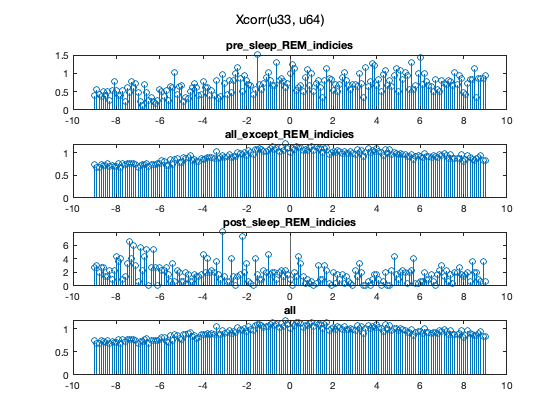


% % Select from valid pairs as opposed to any pairs:
% active_valid_linear_pair_index = 36
% % Get the original pair index from this index:
% 
% active_pair_index =388

% 388 - 4, 20
% active_pair_unit_index = across_experiment_results{active_expt_index}.general_results.indicies.unique_electrode_pairs(active_pair_index,:)

% reverse_lookup_unique_electrode_pairs
% active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_full: num_of_behavioral_state_periods x num_unique_pairs x num_lag_steps] array

% Get the xcorr matrix for only this particular pair (indicated by active_pair_index):
% temp.all.curr_xcorr_forPair = squeeze(active_results.all.pairwise_xcorrelations.xcorr(active_pair_index, :)); % for all behavioral periods (general)

% By behavioral state:
temp.by_behavioral_period.curr_xcorr_forPair = squeeze(active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_full(:, active_pair_index, :)); % [num_of_behavioral_state_periods x num_lag_steps]

figure
subplot(4,1,1)
temp.plotVals = sum(temp.by_behavioral_period.curr_xcorr_forPair(temp.filtered.pre_sleep_REM_indicies, :),1);
temp.plotVals = temp.plotVals ./ temp.plotVals(temp.curr_xcorr_lag_zero_offset); %normalize so that zero-lag has a height of 1
stem(active_results.all.pairwise_xcorrelations.lag_offsets, temp.plotVals);
xline(0);
title('pre_sleep_REM_indicies','Interpreter','none')

subplot(4,1,2)
temp.plotVals = sum(temp.by_behavioral_period.curr_xcorr_forPair(temp.filtered.all_except_REM_indicies, :),1);
temp.plotVals = temp.plotVals ./ temp.plotVals(temp.curr_xcorr_lag_zero_offset); %normalize so that zero-lag has a height of 1
stem(active_results.all.pairwise_xcorrelations.lag_offsets, temp.plotVals);
xline(0);
title('all_except_REM_indicies','Interpreter','none')

subplot(4,1,3)
temp.plotVals = sum(temp.by_behavioral_period.curr_xcorr_forPair(temp.filtered.post_sleep_REM_indicies, :),1);
temp.plotVals = temp.plotVals ./ temp.plotVals(temp.curr_xcorr_lag_zero_offset); %normalize so that zero-lag has a height of 1
stem(active_results.all.pairwise_xcorrelations.lag_offsets, temp.plotVals);
xline(0);
title('post_sleep_REM_indicies','Interpreter','none')

subplot(4,1,4)
temp.plotVals = sum(temp.by_behavioral_period.curr_xcorr_forPair(:, :),1);
temp.plotVals = temp.plotVals ./ temp.plotVals(temp.curr_xcorr_lag_zero_offset); %normalize so that zero-lag has a height of 1
stem(active_results.all.pairwise_xcorrelations.lag_offsets, temp.plotVals);
xline(0);
title('all','Interpreter','none')


temp.curr_fig_title = sprintf('Xcorr(u%d, u%d)', active_unit_A_index, active_unit_B_index);
sgtitle(temp.curr_fig_title)

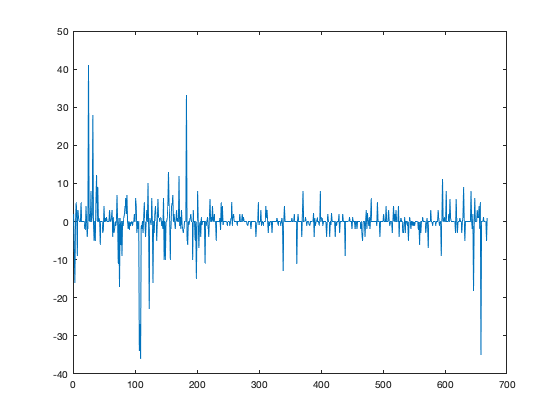



% Temporal Bias "B" as defined in SkaggsMcNaughtonScience1996.pdf:
% One for each behavioral period:
B = sum(temp.by_behavioral_period.curr_xcorr_forPair(:, temp.curr_xcorr_integration_range.upperIndicies),2) - sum(temp.by_behavioral_period.curr_xcorr_forPair(:, temp.curr_xcorr_integration_range.lowerIndicies), 2);

% For all: a scalar quantity:
% B = sum(temp.all.curr_xcorr_forPair(temp.curr_xcorr_integration_range.upperIndicies)) - sum(temp.all.curr_xcorr_forPair(temp.curr_xcorr_integration_range.lowerIndicies));

figure
plot(B)


% Pre-sleep:
B(temp.filtered.pre_sleep_REM_indicies)

ans =            -1
            3
            3
   5.3291e-15
  -6.5061e-17
   -2.841e-16
  -5.6586e-17
           28
            0
            0



B(temp.filtered.post_sleep_REM_indicies)

ans =             0
            0
            0
  -6.5895e-18
           -1
            0
            0
  -4.4546e-16
           -5



%active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_all_periods = squeeze(mean(active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_full, 1)); % [num_unique_pairs x num_lag_steps] array

% active_results.all.pairwise_xcorrelations.xcorr